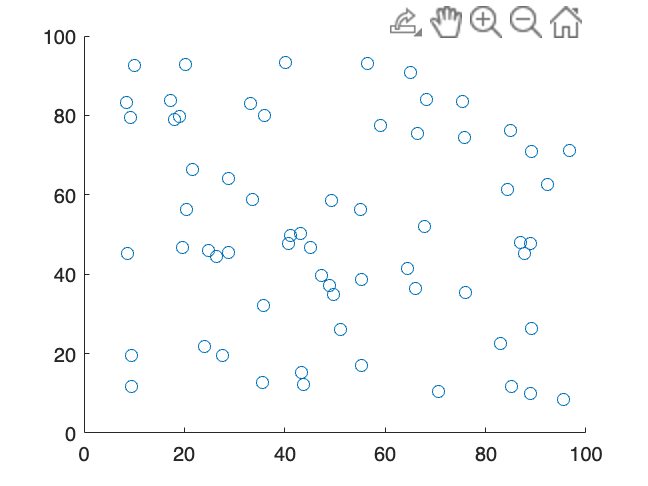

clear all
close all
clc
% 
Array=csvread('graphdataset2.csv');
col1 = Array(:, 1);
col2 = Array(:, 2);
scatter(col1,col2)

T=readtable('graphdataset2.csv');
     %       ^^^^^^^^^------ your csv filename
p=T{:,1:2};
save('mymat.mat','p')
  %   ^^^^^^^^^----- your resulting .mat filename   
% load predefined W matrix for 100 nodes
load mymat
% Matrix = [20,5; 30, -6; 40,8; 50,10];
% for i = 1:size(p,1)
% nsq=sum(X.^2,2);
% K=bsxfun(@minus,nsq,(2*X)*X.');
% K=bsxfun(@plus,nsq.',K);
% K=exp(-K);
% p(i,1)<0 || p(i,2)=
%     disp('neg')
% end
% end
% % calculate combinatorial Laplacian Matrix
% d = sum(p,2);
% L = diag(d)-p;
% 
% % find eigenvector and eigenvalues of combinatorial Laplacian
% [u v]=eig(L);
% 
% 
% % make eignevalue as vector
% v=diag(v);
% % get maximum eigenvalue
% lmax=max(v);
% 
% 
% % create signal where first node is 1 rest of them zero
s=zeros(size(p,1),1);
s(1)=1;
% 
% % determine filter
% flt =exp(-100*v);
% 
% % apply that filter on to graph signal
% sf=u*(flt.*(u'*s));
% 
% % visualize input and result
% %coord=u(:,2:4);
G=gsp_graph(1,p);

GSP_CHECK_WEIGHTS: The diagonal of the weight matrix is not 0!


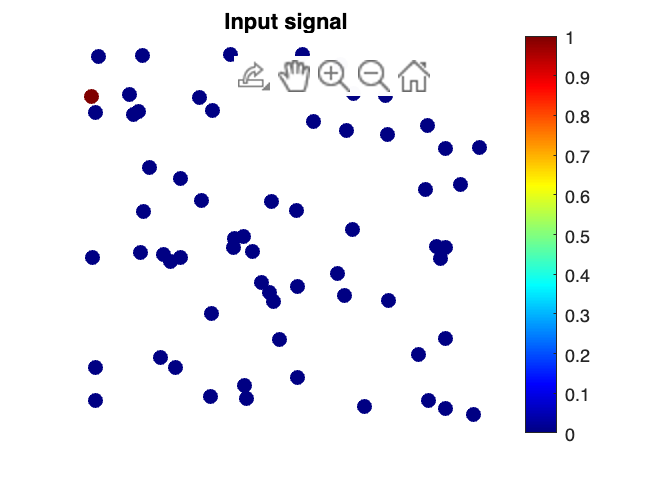

figure;gsp_plot_signal(G,s)
title('Input signal');

% figure;gsp_plot_signal(G,sf)
% title('Filtered signal');
